# (B) Actividad detección de características

Lectura de datos

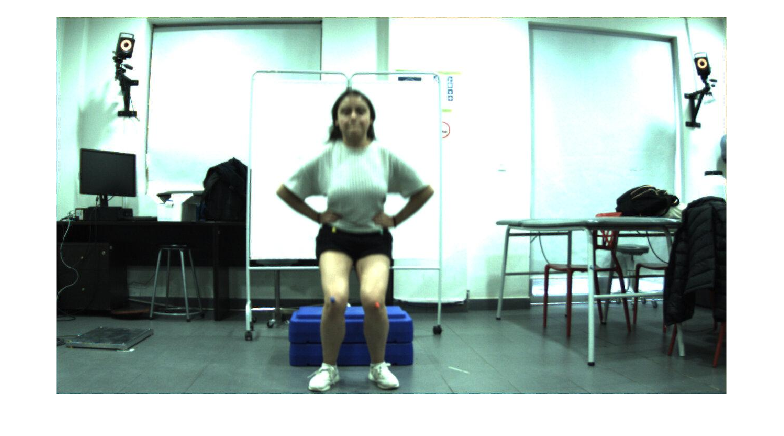

I=imread('../data/rechazo.png');
imshow(I);

Detección de colores

%celda deteccion
[BWred,maskedRGBImageRed] = createMaskRed(I);
[BWblue,maskedRGBImageBlue] = createMaskBlue(I);
[BWskin,maskedRGBImageSkin] = createMaskSkin(I);

Limpieza: borrar elementos pequeño de color piel, mantener objetos azules y rojos solo si estan rodeados de color piel.

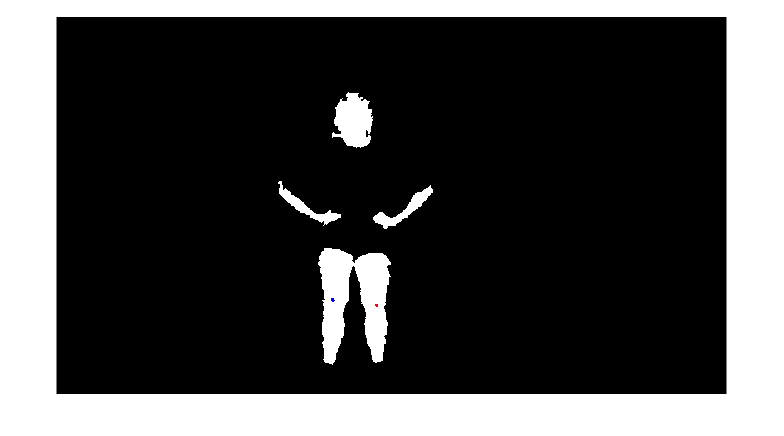

%elimina objetos pequeños
BWskinclean=bwareaopen(BWskin, 1000);
%completa tuneles en la piel
BWskincleanfilled=imfill(BWskinclean, 'holes');

%solo mantemos marcadores "dentro" de la piel
BWred =BWred  & BWskincleanfilled;
BWblue=BWblue & BWskincleanfilled;

%visualizacion de limpieza
%imshow(BWskincleanfilled)

%visualizaremos las 3 mascaras
Ideteccion=zeros([size(BWred,1) size(BWred,2)], 'uint8');
%la piel es blanca (255 en todos los canales)
Ideteccion(:,:,1)=255*BWskincleanfilled;
Ideteccion(:,:,2)=255*BWskincleanfilled;
Ideteccion(:,:,3)=255*BWskincleanfilled;

Ir=Ideteccion(:,:,1);
Ig=Ideteccion(:,:,2);
Ib=Ideteccion(:,:,3);

%el punto rojo sera rojo (255,0,0)
Ir(BWred)=255;
Ig(BWred)=0;
Ib(BWred)=0;

%el punto azul sera azul (0,0,255)
Ir(BWblue)=0;
Ig(BWblue)=0;
Ib(BWblue)=255;

%agrupamos todo en una imagen rgb
Ideteccion(:,:,1)=Ir;
Ideteccion(:,:,2)=Ig;
Ideteccion(:,:,3)=Ib;

imshow(Ideteccion);

Calculo y visualización de vector de orientación

%calculo del vector de orientacion
statsred = regionprops(BWred,'centroid');
Xred=statsred.Centroid(1);
Yred=statsred.Centroid(2);

%origen lo tomamos como el azul
statsblue = regionprops(BWblue,'centroid');
Xblue=statsblue.Centroid(1);
Yblue=statsblue.Centroid(2);

%restamos vectorialmente
X=Xred-Xblue;
Y=Yred-Yblue;

angle=atand(Y/X);
fprintf('El angulo es %f', angle);

El angulo es 7.130960

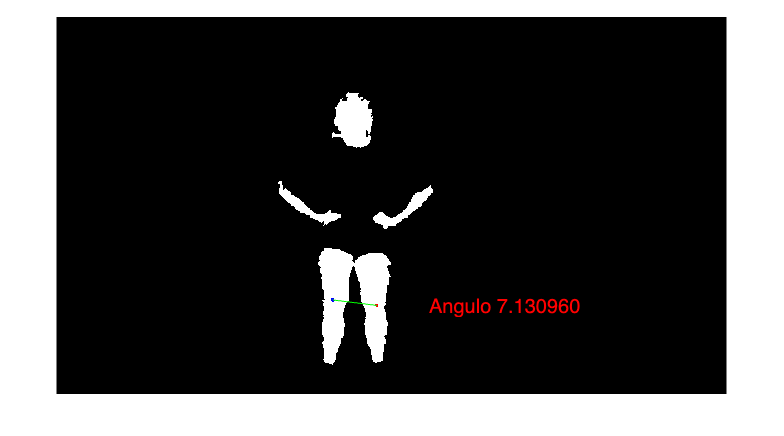


%visualizamos: imagen, el segmento de recta, y el angulo
imshow(Ideteccion);
hold on,
plot([Xblue Xred], [Yblue Yred], 'g');
hold on,
text(Xred+100,Yred,sprintf('Angulo %f', angle), 'Color', 'r');